## Path names

fn_base = 'Z:\\All_Staff';
gk_fn = fullfile(fn_base, 'home\gloria\Analysis\2P');
tc_fn = fullfile(gk_fn, '\tutorial'); 
mworks_fn = fullfile(fn_base, 'Behavior\Data');
fnout = fullfile(gk_fn, '\oriAnalysis'); 

## Specific experiment information

date = '220428'; 
ImgFolder = '003'; 
time = '1115';
mouse = 'i2516'; 
mouse_mworks = 'i''i2516''';
frame_rate = 15.5; 
run_str = catRunName(ImgFolder, 1); 
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run_str];

## Load mWorks and TC data

Load mworks data and neuropil-subtracted time course data from the tutorial

fName = fullfile(mworks_fn, ['data-' mouse_mworks '-' date '-' time '.mat']);
load(fName);

CD = fullfile(tc_fn, datemouse, datemouserun);
cd(CD);
timecourse = [datemouserun '_TCs.mat'];
load(timecourse); 

## 1. Transform TCs into trial matrix

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials

nOn = input.nScansOn; % # frames on
nOff = input.nScansOff; % # frames off
nFramesPerTrial = nOn+nOff;
ntrials = size(input.tGratingDirectionDeg,2);
ncells = size(npSub_tc,2);

    Reshape npSub_tc (nframes x ncells) into a matrix that is nFrames/Trial x nTrials x ncells

F_matrix = reshape(npSub_tc,[nFramesPerTrial, ntrials, ncells]);
fprintf(['Size of F_matrix is ' num2str(size(F_matrix))])

Size of F_matrix is 90  640  171

    b. Create baseline F (F0) matrix by averaging from last half of off period

F0_matrix = mean(F_matrix(nOff/2:nOff,:,:)); 

    c. Find dF/F for each trial

dFoF = (F_matrix-F0_matrix)./F0_matrix;

## 2. Identify cells that are significantly responsive to at least one direction

    a. Define two analysis windows- base_win and resp_win

base_win = [30:59];
resp_win = [61:90];

    b. Create two matrices: base (a ncells x ntrials matrix with the average response during the baseline window) and resp (a ncells x ntrials matrix with the average response during the response window).

base = squeeze(mean(dFoF(base_win,:,:))); 
resp = squeeze(mean(dFoF(resp_win,:,:))); 

    c. Create a “for” loop where you loop through each direction and select the set of trials for that direction and use a “ttest” to compare the baseline and stimulus response across those trials.

Dirs = celleqel2mat_padded(input.tGratingDirectionDeg); % directions of each trial
unique_Dirs = unique(Dirs); % what are the directions
nDirs = length(unique_Dirs); % how many directions
bonferroni = (.05/(nDirs-1)); % bonferroni correction for multiple comparisons

h = zeros(nDirs,ncells); % creates a matrix for outcome of ttest (hypothesis)
p = zeros(nDirs,ncells); % creates a matrix for outcome of ttest (p-values)
avg_resp = zeros(nDirs,ncells); % average response of each cell to each direction
std_err = zeros(nDirs,ncells); % standard error for avg response
indices = cell(1, nDirs); % cell array of indices at which each direction appears

for i = 1:nDirs
    ind = find(Dirs == unique_Dirs(i)); % array of all trials for specific direction
    indices{i} = ind; % adds array of trials for that direction in cell array
    b = base(ind,:); % df/f for baseline window on trials of specific direction
    r = resp(ind,:);  %df/f for response window on trials of specific direction
    [h(i,:) p(i,:)] = ttest(b,r,'Alpha',bonferroni,'tail','left'); %t test of bl vs resp means for given direction
    avg_resp(i,:) = mean(r,1); % avg response of each cell at each direction
    std_err(i,:) = (std(r,1))/(sqrt(length(nDirs))); % std error of response at each direction
end

    How many cells are significant for at least one direction?

sig_Dirs = zeros(1,ncells);

for i = 1:ncells
    sig_Dirs(i) = sum(h(:,i)); %sum of all direction significance values (0 or 1) for each cell
end

n_sig_Dirs = sum(sig_Dirs>=1)

n_sig_Dirs = 170

    How many are significant if you don’t do the bonferonni correction (alpha  = 0.05)? Why do we use this correction?

for i = 1:nDirs
    ind = find(Dirs == unique_Dirs(i));
    b = base(ind,:); 
    r = resp(ind,:);
    [h_2(i,:) p_2(i,:)] = ttest(b,r,'tail','left'); 
end

sig_Dirs_2 = zeros(1,ncells);

for i = 1:ncells
    sig_Dirs_2(i) = sum(h_2(:,i)); 
end

n_sig_Dirs_2 = sum(sig_Dirs_2>=1)

n_sig_Dirs_2 = 171

## 3. Plot the average tuning curve for all cells in the field of view

i.e. each cell’s stimulus response to each direction

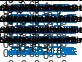

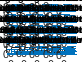

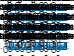

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    errorbar(unique_Dirs,avg_resp(:,i),std_err(:,i)) % plot with error bars of all orientations for a given cell
    hold on
    title(['# of Significant Directions = ', num2str(sig_Dirs(i))], "FontSize", 6.5)
    start = start+1;
end

## 4. Fit data with a von Mises function

    a. Use your baseline and response matrices to create a new matrix of baseline subtracted responses for each trial (resp-base).

bl_sub_resp = resp-base;

    b. Make a for loop where you loop through each cell and use the function miaovonmisesfit_dir. The inputs should be the directionsthat you presented (theta, 1 x nDirs) and the average response of each cell to each direction.

clear b r
dir_rads = deg2rad(unique_Dirs); % change theta from degrees to radians
b = zeros(1,ncells);
R1 = zeros(1,ncells);
R2 = zeros(1,ncells);
k1 = zeros(1,ncells); % the sharpness of the direction tuning
u1 = zeros(1,ncells); % the preferred direction
u2 = zeros(1,ncells);
sse = zeros(1,ncells); % sum of squared error
R_square = zeros(1,ncells);

for i = 1:ncells
    [b(i) k1(i) R1(i) R2(i) u1(i) u2(i) sse(i) R_square(i)] = miaovonmisesfit_dir(dir_rads,avg_resp(:,i));
end

    c.  Then you can add the fit to your plot of each cell (from 2a-d).

y_fit = zeros(360,ncells);
new_Dirs = deg2rad(0:1:359);

for i = 1:ncells
    b_fit = b(i);
    R1_fit = R1(i);
    k1_fit = k1(i);
    u1_fit = u1(i);
    y_fit(:,i) = b_fit+R1_fit.*exp(k1_fit.*(cos(2.*(new_Dirs-u1_fit))-1));
end

    d. What is the preferred direction of each cell?

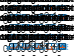

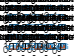

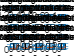

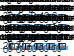

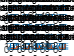

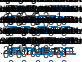

[pref_Dir_val pref_Dir_deg] = max(y_fit,[],1);

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    errorbar(unique_Dirs,avg_resp(:,i),std_err(:,i)) % plot with error bars of all directions for a given cell
    hold on
    plot(y_fit(:,i)); % plot the fits
    vline(pref_Dir_deg(i),'black'); % indicate preferred direction
    title(['# of Significant Directions = ', num2str(sig_Dirs(i))], "FontSize", 6.5)
    start = start+1;
end

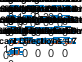

hold off;

## 5. Plot time courses of each cell at its preferred direction

  a. Make a for loop where you loop through each cell and plot responses in all of the trials it was at its preferred orientation

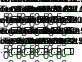

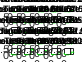

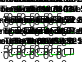

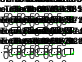

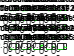

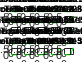

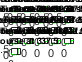

[max_resp, max_ind ] = max(avg_resp, [], 1); % output gives the numerical maximum average response (max_resp) and which direction index it occurs at (max_ind) for each cell
avg_pref_trials = zeros(nFramesPerTrial, ncells);

for i = 1:ncells
    pref_trials{i} = indices{max_ind(i)}; %cell array of all trial numbers the preferred direction is shown for each cell
    avg_pref_trials(:,i) = mean(dFoF(:,pref_trials{i},i),2); % for each cell, find the mean response across all trials with preferred direction for each frame
end

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    plot(avg_pref_trials(:,i), "green") % plot time course of preferred direction for a given cell
    axis([0 90 0 0.6])
    vline(60,'black'); % indicate when stimulus is on
    hold on
    title(['Time course at ', num2str(unique_Dirs(max_ind(i)))], "FontSize", 6.5)
    start = start+1;
end

## 7. Plot time courses of each cell orthogonal to its preferred direction

  a. Make a for loop where you loop through each cell and find all of the trials it was orthogonal to its preferred orientation

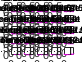

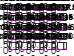

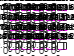

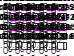

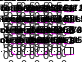

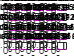

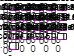

ortho_ind = zeros(1, ncells); % matrix of every cell's orthogonal direction index
avg_ortho_trials = zeros(nFramesPerTrial, ncells);

for i = 1:ncells
    ortho_ind(i) = max_ind(i)+4; % finds the index of each cell's the orthogonal direction by shifting over the index by 4
    if ortho_ind(i)>16
        ortho_ind(i) = ortho_ind(i)-16; % if the index exceeds 16, this is beyond a full revolution and must be adjusted (-360 degrees)
        ortho_trials{i} = indices{ortho_ind(i)}; % cell array of all trial numbers the orthogonal direction is shown for each cell
    end
    avg_ortho_trials(:,i) = mean(dFoF(:,ortho_trials{i},i),2); % for each cell, find the mean response across all trials with orthogonal direction for each frame
end

figure;
if ncells<25
    [n n2] = subplotn(ncells);
else
    [n n2] = subplotn(25);
end

start = 1; % which figure you're on
x = 0; % which subplot in the designated figure you're on
for i = 1:ncells
    if start > 25
        start = 1;
        x = x+1;
        figure;
    end
    subplot(n,n2,i-(x.*25)) % which subplot position
    plot(avg_ortho_trials(:,i), "magenta") % plot time course of orthogonal direction for a given cell
    axis([0 90 0 0.6])
    vline(60,'black'); % indicate when stimulus is on
    hold on
    title(['Time course at ', num2str(unique_Dirs(ortho_ind(i)))], "FontSize", 6.5)
    start = start+1;
end

## 8. Average response of all the cells at their preferred vs. orthogonal direction

avg_pref_allcells = zeros(nFramesPerTrial, 1);
avg_ortho_allcells = zeros(nFramesPerTrial, 1);
std_err_pref = zeros(nFramesPerTrial, 1);
std_err_ortho = zeros(nFramesPerTrial, 1);

avg_pref_allcells(:,1) = mean(avg_pref_trials(:,:),2); % averages response across all cells to their preferred direction for each frame in the trial
avg_ortho_allcells(:,1) = mean(avg_ortho_trials(:,:),2); % averages response across all cells to their orthogonal direction for each frame in the trial
std_err_pref(:,1) = (std(avg_pref_trials,0,2))/(sqrt(length(avg_pref_allcells))); % standard error across all cells to their preferred direction for each frame in the trial
std_err_ortho(:,1) = (std(avg_ortho_trials,0,2))/(sqrt(length(avg_ortho_allcells))); % standard error across all cells to their orthogonal direction for each frame in the trial

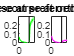

figure;
subplot(1,2,1)
shadedErrorBar([],avg_pref_allcells(:),std_err_pref(:), "green"); % plot average time course with error bars of preferred direction across all cells
axis([0 90 0 0.3])
vline(60,'black'); % indicate when stimulus is on
hold on
title(['Avg time course at preferred direction'], "FontSize", 9)

subplot(1,2,2)
shadedErrorBar([],avg_ortho_allcells(:), std_err_ortho(:), "magenta"); % plot average time course with error bars of orthogonal direction across all cells
axis([0 90 0 0.3])
vline(60,'black'); % indicate when stimulus is on
hold on
title(['Avg time course at orthogonal direction'], "FontSize", 9)

## 9.  Incorporating running data

    a. Determine this animal was running and divide trials between running and not running

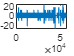

[wheel_speed] = wheelSpeedCalc(input,32,'purple'); % arguments: the name of your mWorks input structure, the number of clicks in a rotation of the encoderm (32), and which wheel used (orange, purple, or red)

figure; 
plot(wheel_speed) % plots the time course of the wheel speed in frames

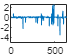

wheel_tc = zeros(nOn+nOff, ntrials); % segregates wheel speed time course into trials
for iTrial = 1:ntrials
    wheel_tc(:,iTrial) = wheel_speed(1+((iTrial-1).*(nOn+nOff)):iTrial.*(nOn+nOff));
end
wheel_trial_avg = mean(wheel_tc(nOff:nOn+nOff,:),1); % average wheel speed over each trial
figure; movegui('center')
plot(wheel_trial_avg) % plots average wheel speed over trials


RIx = wheel_trial_avg>.5; % threshold to determine which trials are running (0 = false, 1 = true)

    b. Average time course across cells for running vs. not running

run_ind = find(RIx); % indices of all running trials
notrun_ind = find(~RIx); % indices of all not running trials
avg_run_trials = zeros(nFramesPerTrial, ncells);
avg_notrun_trials = zeros(nFramesPerTrial, ncells);
avg_run_allcells = zeros(nFramesPerTrial, 1);
avg_notrun_allcells = zeros(nFramesPerTrial, 1);
std_err_run = zeros(nFramesPerTrial,1);
std_err_notrun = zeros(nFramesPerTrial, 1);

for i = 1:ncells
    avg_run_trials(:,i) = mean(dFoF(:,run_ind,i),2); % for each cell, find the mean response across all running trials for each frame
    avg_notrun_trials(:,i) = mean(dFoF(:,notrun_ind,i),2); % for each cell, find the mean response across all not-running trials for each frame
end

avg_run_allcells(:,1) = mean(avg_run_trials(:,:),2); % averages response across all cells for each frame in running trial
avg_notrun_allcells(:,1) = mean(avg_notrun_trials(:,:),2); % averages response across all cells for each frame in not-running trial
std_err_run(:,1) = (std(avg_run_trials,0,2))/(sqrt(ncells)); % standard error across all cells for each frame in running trial
std_err_notrun(:,1) = (std(avg_notrun_trials,0,2))/(sqrt(ncells)); % standard error across all cells for each frame in non-running trial

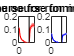

figure;
subplot(1,2,1)
shadedErrorBar([],avg_run_allcells(:),std_err_run(:), "red"); % plot average time course with error bars of running trials across all cells
axis([0 90 0 0.2])
vline(60,'black'); % indicate when stimulus is on
hold on
title(['Avg time course for running trials'], "FontSize", 9)

subplot(1,2,2)
shadedErrorBar([],avg_notrun_allcells(:), std_err_notrun(:), "blue"); % plot average time course with error bars of not-running trials across all cells
axis([0 90 0 0.2])
vline(60,'black'); % indicate when stimulus is on
hold on
title(['Avg time course for not-running trials'], "FontSize", 9)

c. Balance running vs. not running trials

for i = 1:nDirs
    run_trials{i} = intersect(run_ind,indices{i});
    notrun_trials{i} = intersect(notrun_ind,indices{i});
    notrun_subsample{i} = randsample(notrun_trials{i}, length(run_trials{i}));
end